## Define System

syms Fx theta theta_dot theta_ddot x x_dot x_ddot M m g l;

M_v = 1;     % cart mass [kg]
m_v = 0.1;     % pole mass [kg]
l_v = 0.5;     % pole COM length [m]
g_v = 9.81;    % gravity [m/s^2]
a = g_v/l_v;
b = 1/l_v;
P = 10;
q2 = 1;   
q2_s = 2;   
theta_desired = -pi;
phi_desired = 0;

x_ddot = (Fx + m*g*cos(theta)*sin(theta) ...
     + m*l*sin(theta)*theta_dot^2)/(M + m*sin(theta)^2)

$$x\_ddot = \frac{l\,m\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}+\mathrm{Fx}+g\,m\,\cos\left(\theta \right)\,\sin\left(\theta \right)}{m\,{\sin\left(\theta \right)}^{2}+M}$$

theta_ddot = -(Fx*cos(theta) + (M + m)*g*sin(theta) + ...
    m*l*sin(theta)*cos(theta)*theta_dot^2)/(l*(M + m*sin(theta)^2))

$$theta\_ddot = -\frac{l\,m\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}+\mathrm{Fx}\,\cos\left(\theta \right)+g\,\sin\left(\theta \right)\,\left(M+m\right)}{l\,\left(m\,{\sin\left(\theta \right)}^{2}+M\right)}$$


Cons = [M; m; g; l];
X = [x; x_dot; theta; theta_dot];
f = [x_dot; x_ddot; theta_dot; theta_ddot]

$$f = \left(\begin{array}{c} \dot{x}\\ \frac{l\,m\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}+\mathrm{Fx}+g\,m\,\cos\left(\theta \right)\,\sin\left(\theta \right)}{m\,{\sin\left(\theta \right)}^{2}+M}\\ \dot{\theta }\\ -\frac{l\,m\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}+\mathrm{Fx}\,\cos\left(\theta \right)+g\,\sin\left(\theta \right)\,\left(M+m\right)}{l\,\left(m\,{\sin\left(\theta \right)}^{2}+M\right)} \end{array}\right)$$



Eq_val = [0; 0; theta_desired; 0; 0; M_v; m_v; g_v; l_v];

A = jacobian(f,X);
A_d = subs(A,[X;Fx;Cons],Eq_val)

$$A\_d = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & \frac{981}{1000} & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & \frac{10791}{500} & 0 \end{array}\right)$$

A_d = double(A_d);

B = jacobian(f,Fx);
B_d = subs(B,[X;Fx;Cons],Eq_val)

$$B\_d = \left(\begin{array}{c} 0\\ 1\\ 0\\ 2 \end{array}\right)$$

B_d = double(B_d);

C = eye(4);
D = [0;0;0;0];

## LQR

Q = [1 0 0 0;
     0 1 0 0;
     0 0 10 0;
     0 0 0 5];
R = 1;

[K_LQR, ~, P_LQR] = lqr(A_d,B_d,Q,R)

K_LQR =    -1.0000   -2.2682   31.1210    7.1233


P_LQR =   -0.7927 + 0.5013i
  -0.7927 - 0.5013i
  -3.0284 + 0.0000i
  -7.3647 + 0.0000i


## **Potential Energy Slope**

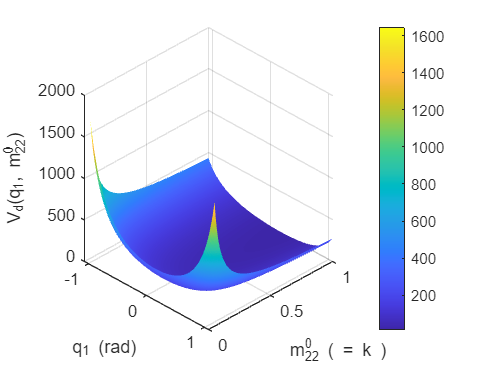

%% Ranges
q1 = linspace(-pi/2 + 0.5, pi/2 - 0.5, 400);  % q1 axis
k_vec = linspace(0.05, 1.0, 250);             % k axis (also m22_0)

%% Create grid
[Q1, K] = meshgrid(q1, k_vec);

%% Assume m22_0 = k
m22_0 = K;

%% Compute z(q1,k)
Z = (q2 - q2_s) ...
    + (3./b) .* log(sec(Q1) + tan(Q1)) ...
    + (6.*m22_0 ./ (K.*b)) .* tan(Q1);

%% Compute V_d(q1,k)
Vd = (3*a) ./ (K.*b^2 .* cos(Q1).^2) ...
     + (P/2) .* (Z.^2);

%% Plot 3D surface
figure;
surf(Q1, m22_0, Vd, 'EdgeColor','none');
grid on;
xlabel('q_1 (rad)');
ylabel('m_{22}^0 ( = k )');
zlabel('V_d(q_1, m_{22}^0)');

view(45,30);
colorbar;

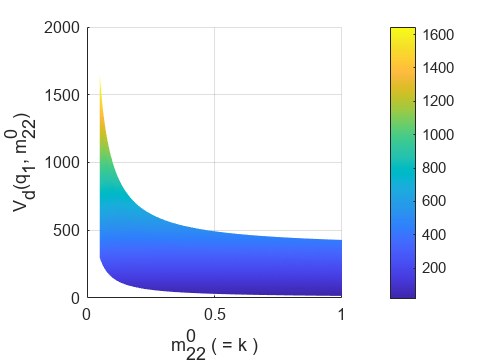


%% Plot 3D surface
figure;
surf(Q1, m22_0, Vd, 'EdgeColor','none');
grid on;
xlabel('q_1 (rad)');
ylabel('m_{22}^0 ( = k )');
zlabel('V_d(q_1, m_{22}^0)');
view(90,0);
colorbar;

#### **Find Best k for m22_0**

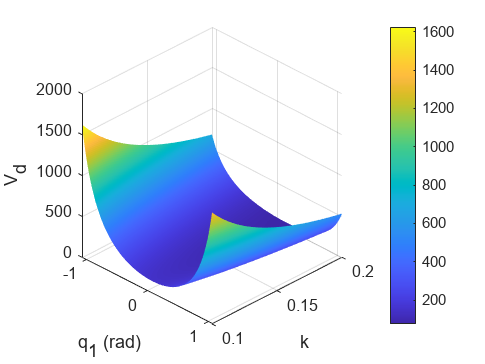

m22_0 = 0.2;    % FIXED as requested

%% Ranges
q1 = linspace(-pi/2 + 0.5, pi/2 - 0.5, 400);
k_vec = linspace(0.1, 0.2, 250);   % k < 0.2

%% Grid
[Q1, K] = meshgrid(q1, k_vec);

%% Compute z(q1,k)
Z = (q2 - q2_s) ...
    + (3/b) .* log(sec(Q1) + tan(Q1)) ...
    + (6*m22_0 ./ (K*b)) .* tan(Q1);

%% Compute V_d
Vd = (3*a) ./ (K .* b^2 .* cos(Q1).^2) ...
     + (P/2) .* (Z.^2);

%% Plot
figure;
surf(Q1, K, Vd, 'EdgeColor','none');
xlabel('q_1 (rad)');
ylabel('k');
zlabel('V_d');
colorbar;
view(45,30);
grid on;

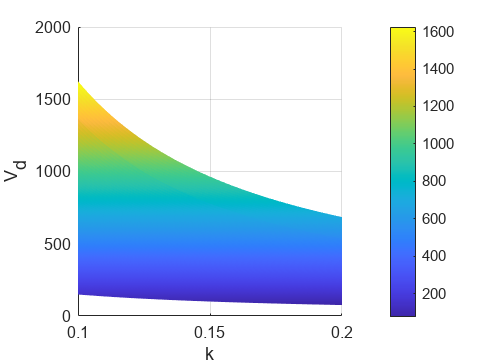


%% Plot
figure;
surf(Q1, K, Vd, 'EdgeColor','none');
xlabel('q_1 (rad)');
ylabel('k');
zlabel('V_d');
colorbar;
view(90,0);
grid on;

Outputs

t  = out.E.Time;

Unable to resolve the name 'out.E.Time'.

e  = out.E.Data;
tr = out.Trig.Data;

figure
hold on
grid on

hE = plot(t, e, 'b', 'LineWidth', 1.5);

yl = ylim;

tr_diff   = diff([0; tr; 0]);
start_idx = find(tr_diff == 1);
end_idx   = find(tr_diff == -1) - 1;

for k = 1:length(start_idx)
    x1 = t(start_idx(k));
    x2 = t(end_idx(k));
    
    hPatch = patch([x1 x2 x2 x1], ...
                   [yl(1) yl(1) yl(2) yl(2)], ...
                   'r', ...
                   'FaceAlpha', 0.15, ...
                   'EdgeColor', 'none');
end

uistack(hE,'top')

xlabel('Time (s)')
ylabel('E')

legend([hE hPatch], {'E','IDA-PBC Active'})